依赖统一实验分析作图v17.1.0

DataSetBas=UniExp.DataSet(MATLAB.UITools.OpenFileDialog(Filter='UniExp数据库|*.mat',Title='选择UniExp数据库'));%"\\Data-Server-1\个人数据\TeamVYL\数据库\基本迁移行为v1.mat - 快捷方式.lnk"
DataSetBas.Mice.Group=categorical(DataSetBas.Mice.Group);

SessionTableAL=DataSetBas.TableQuery(["Mouse","DateTime","Performance","Group"],Group="声光水",Design="LightWater");
SessionTableLL=DataSetBas.TableQuery(["Mouse","DateTime","Performance","Group"],Group="光声水",Design="LightWater");
SessionTableAA=DataSetBas.TableQuery(["Mouse","DateTime","Performance","Group"],Group="声光水",Design="AudioWater");
SessionTableLA=DataSetBas.TableQuery(["Mouse","DateTime","Performance","Group"],Group="光声水",Design="AudioWater");
SummaryL=UniExp.LearningSummarize([SessionTableAL;SessionTableLL]);SummaryA=UniExp.LearningSummarize([SessionTableAA;SessionTableLA]);

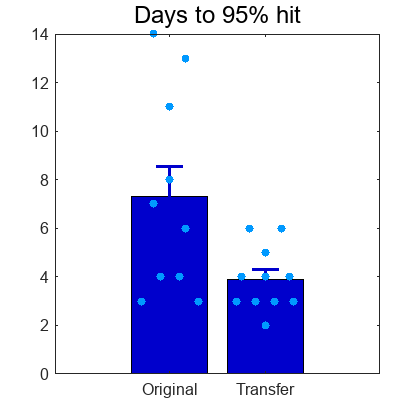

Colors1=jet(20);Ax = gca;
UniExp.BarScatterCompare([{SummaryL.LearnedDays{1}.Day},{SummaryL.LearnedDays{2}.Day}],Colors1([2 6],:));
Ax.XTickLabel=['Original';'Transfer'];MATLAB.Graphics.FigureAspectRatio(1,1,MATLAB.Flags.Narrow);
Ax.FontSize=12;
title('Days to 95% hit','fontsize',18);
savefig('\\Data-Server-1\个人数据\杨青宁\202401\fig1c-Days to 95% hit');
print('\\Data-Server-1\个人数据\杨青宁\202401\fig1c-Days to 95% hit.svg','-dsvg');